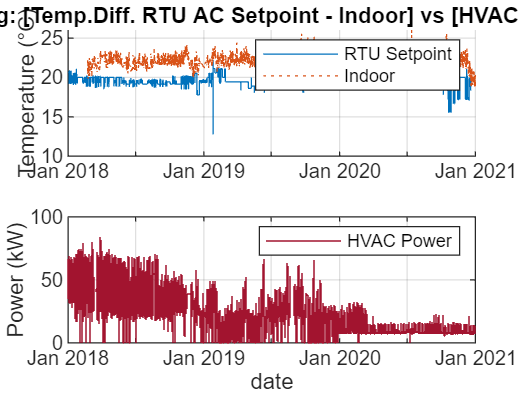

clf;

figure('Name','north_temp_diff_rtu_outdoor_vs_energy_use');

subplot(2,1,1);
title('North Wing: [Temp.Diff. RTU AC Setpoint - Indoor] vs [HVAC Energy Use]');
hold on;
ax1 = stairs(rtu_sa_t_sp.date, rtu_sa_t_sp.rtu_north, 'Color', '#0072BD', 'LineWidth', 0.5, 'LineStyle', '-');
ax2 = stairs(zone_temp.date, mean([zone_temp.north_gf,zone_temp.north_2f],2), 'Color', '#D95319', 'LineWidth', 0.5, 'LineStyle', ':');
legend('RTU Setpoint', 'Indoor');
ylabel('Temperature (°C)');
grid on;

subplot(2,1,2);
ax0 = stairs(ele.date, ele.hvac_N, 'Color', '#A2142F', 'LineWidth', 0.4);
legend('HVAC Power');
ylabel('Power (kW)');
xlabel('date');
grid on;

linkaxes([ax1.Parent,ax2.Parent,ax0.Parent], 'x');

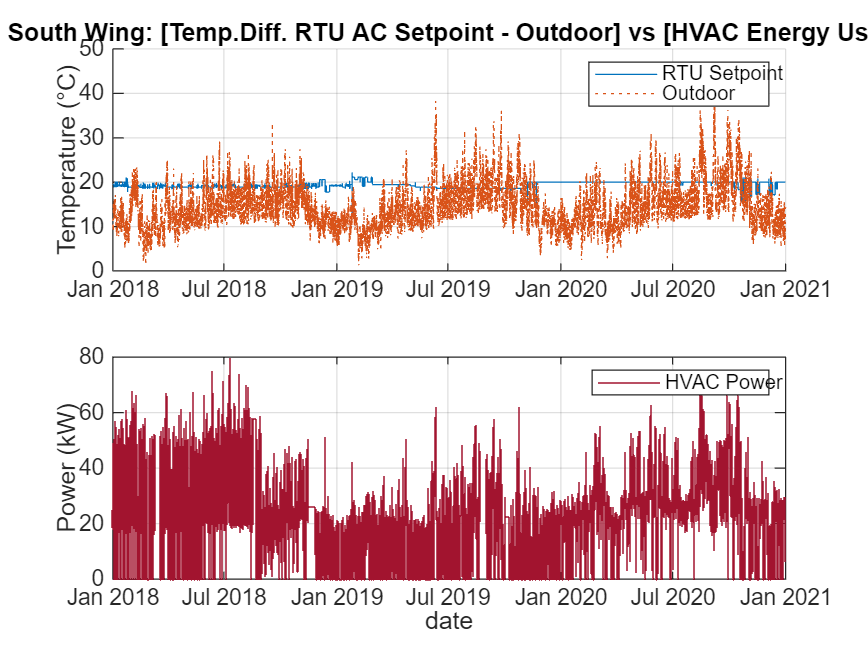

clf;

figure('Name','south_temp_diff_rtu_outdoor_vs_energy_use');

subplot(2,1,1);
title('South Wing: [Temp.Diff. RTU AC Setpoint - Indoor] vs [HVAC Energy Use]');
hold on;
ax1 = stairs(rtu_sa_t_sp.date, rtu_sa_t_sp.rtu_south, 'Color', '#0072BD', 'LineWidth', 0.5, 'LineStyle', '-');
ax2 = stairs(zone_temp.date, mean([zone_temp.south_gf,zone_temp.south_2f],2), 'Color', '#D95319', 'LineWidth', 0.5, 'LineStyle', ':');
legend('RTU Setpoint', 'Indoor');
ylabel('Temperature (°C)');
grid on;

subplot(2,1,2);
ax0 = stairs(ele.date, ele.hvac_S, 'Color', '#A2142F', 'LineWidth', 0.4);
legend('HVAC Power');
ylabel('Power (kW)');
xlabel('date');
grid on;

linkaxes([ax1.Parent,ax2.Parent,ax0.Parent], 'x');